# System parameter calculutions

The goal of this script is to compute the dimensions of the various diemnsions of the parts of the 2 stage zero stiffness variable position and mass gravity compensation. It does so using the given constraints, prefrences and part selection 

### Material constants

clear all; close all;
g = 9.81; %[m/s^2]   gravity constant  
%alluminium
E_allu = 69E9; %   
sigma_y_allu = 124E6; 
%steel https://www.steelinox.nl/nl/informatie/roestvast-staal-info
%https://www.gamma.nl/assortiment/plat-profiel-rvs-15x0-5x1000mm/p/B175454
E_steel = 190E9; %[Pa] elastic modulus of steel 
sigma_y_steel = 250E6; %[Pa] yield stress steel
%pvc -> https://www.naeff.nl/nl/technische-datasheet/polyvinylchloride-pvc-u?n=2690_3
%https://www.praxis.nl/gereedschap-installatiemateriaal/ijzerwaren/profielen-platen/profielen/alberts-platte-stang-kunststof-wit-25x2mm-1m/5535075
E_pvc = 3000E6; %[Pa]
sigm_y_pvc = 58E6; %[Pa] %flow tension is used, as this is an underirable effect

### System constants

m2 = .8; %[Kg] unloaded mass
m1 = m2 + 2; %[Kg] loaded mass
sys_angle = 28/180*pi; %[rad] angle at which the mirror is located 
t = 6e-3; %[m] thickness of plate material that will be used for construction

### Constraints

h_max = .4; %[m] maximal height mass compensator     
w_max  = .1; %[m] maximal width mass compensator   
sf = 1.1; %safety margin 10%

### Requirements

d_mirror = .16 

d_mirror = 0.1600

Longstroke = d_mirror*sin(sys_angle)*3 %[m] stroke of the first stage

Longstroke = 0.2253

S1 = Longstroke*sf

S1 = 0.2479

S1 = 160E-3

S1 = 0.1600

S2 = 5e-3

S2 = 0.0050

# First stage parameters

The first stage has and adjustment screw, clamp and spiral pulley, here it is desirable to have low stiffness of the spring such that the size of the spiral pulley can be minimized

### Variable parameters

R_i = 15E-3; %[m] inner radius -> constraint by material design of the pulley system
R_o = 0; %[m] outer radius -> design prefrences to keep the system compact -> limited by the tickness of the legs of the system
F1 = m1*g %[N] initial load on the system

F1 = 27.4680

F2 = m2*g %[N] second loading condition

F2 = 7.8480

SR = 1/3; %spring elongation ratio
h_mech = 5*t% 5 plate material of space needed for construction     

h_mech = 0.0300

### Spring Calculations

for i = 1:100 %loop to optimize system parameters
    k1 = round( ((1+1/(1-SR) )*F1-F2)/(h_max-R_o-h_mech-S1/(1-SR)));
    R_o = F1/k1;
end
k1, R_o

k1 = 679

R_o = 0.0405

h_adjust = (F1 - F2)/k1; %adjustment height
Lmax = h_max - R_o - h_mech - h_adjust %maximum length of the spring

Lmax = 0.3007

L_0 = Lmax*SR %initial length spring

L_0 = 0.1002

L1 = F1/k1 %initial elongation (without initial length)

L1 = 0.0405

L2 = F2/k1 %second elongation (without initial length)

L2 = 0.0116

R_o + S1 + L1 + L_0 + h_adjust + h_mech %check should be equal to maximal length

ans = 0.4000

### Spiral pulley

pulley_margin = 1.4; %factor to increase pulley size
F_0 = F1

F_0 = 27.4680

k = k1;
r1 = R_i/pulley_margin

r1 = 0.0107

r1 = 0.01 %[m]

r1 = 0.0100

r2 = F_0/k

r2 = 0.0405

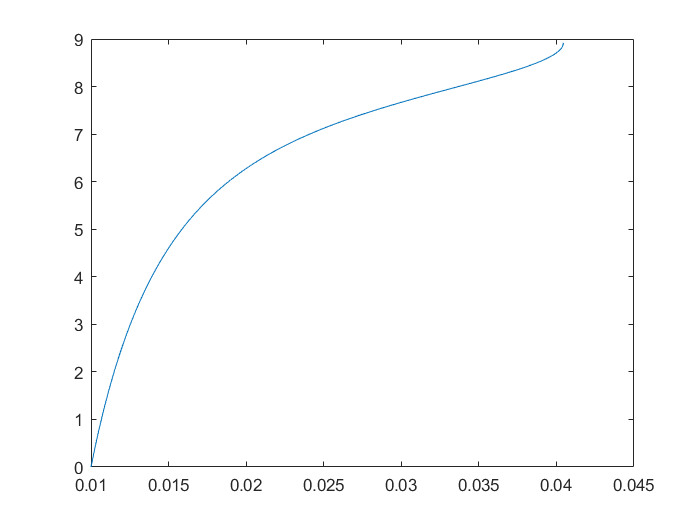

S = F_0*r2/k;
T = F_0*r2/(k*r1);
n_steps = 800;
stepsize = (r2- r1)/n_steps;
r = [r1:stepsize:r2];
theta = -sqrt(S^2- r.^4)./(2*r.^2) + 0.5 *asin(r.^2/S) ;
const = theta(1);
theta = theta - const; %adding constant such that theta(1) = 0
theta(r > sqrt(S)) = angle(theta(r > sqrt(S)));

figure()
clf
plot(r,theta)

### Plotting shape

x = real(cos(theta).*r*1e3);
y = real(sin(theta).*r*1e3);
output = table(transpose(x),transpose(y))

output = 801×2 table
     Var1      Var2 
    ______    ______

        10         0
    10.019    0.6249
    9.9989    1.2451
     9.942    1.8584
    9.8491    2.4627
    9.7213     3.056
    9.5602    3.6364
     9.367    4.2024
    9.1432    4.7524
    8.8905    5.2848
    8.6102    5.7985
    8.3041    6.2923
    7.9736     6.765
    7.6206    7.2159
    7.2464    7.6441
    6.8528    8.0489


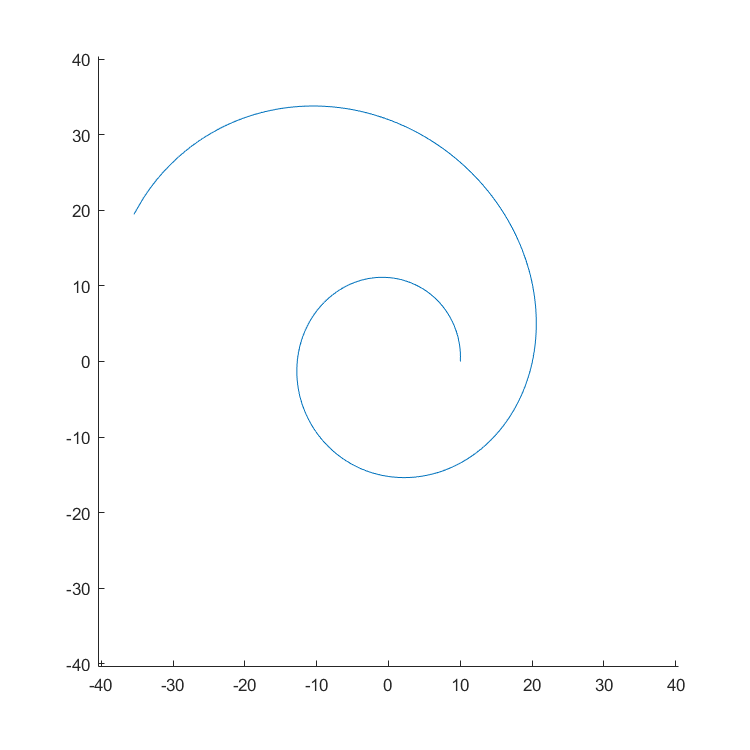

writetable(output,'curve.xlsx')

figure()
clf
hold on
set(gcf, 'Position',  [100, 100, 600, 600])
plot(x,y)
plot(0,0)
xlim([-r2,r2]*1e3)
ylim([-r2,r2]*1e3)

# Second stage parameters

R = 0.9; %stiffness reduction
n = 4; %number of leaf springs
h2 = h_max -2*R_o - S1 %second stage maximal height

h2 = 0.1591

h2 = round(h2,2); %rounding to 
h2*1e3

ans = 160


h2n = 8*S2; %for the negative spring we need about 3 times more than the stroke 
h2p = h2 - h2n

h2p = 0.1200

h2n*1e3

ans = 40

round(h2p*1e3)

ans = 120

### Positive spring design

hm2p = h2p/2 %mechnism height needed for construction

hm2p = 0.0600

ha2p = 0;
kp = round( ((1+1/(1-SR) )*F1-F2)/(h2p-hm2p-S2-ha2p/(1-SR)))

kp = 1106

ha2p = (F1 - F2)/kp %possible height adjustment

ha2p = 0.0177

stroke = 1 / (1- R)*ha2p %possible output stroke with current adjustment methdod (excl mass adjustment) (most of this stroke goes to mass adjustment)

stroke = 0.1774

Lmax = h2p - ha2p - hm2p %maximum length of the spring

Lmax = 0.0423

L_0 = Lmax*SR %initial length spring

L_0 = 0.0141

(Lmax - L_0)*1e3 %total stroke of adjustment mechanism

ans = 28.1736

L_0*1e3

ans = 14.0868

L1 = F1/kp %initial elongation (without initial length)

L1 = 0.0248

L2 = F2/kp; %second elongation (without initial length)
hm2p + ha2p + L_0 + L1 + S2 %should be equal to the 

ans = 0.1217

### Negative spring design

sm = 0.87; %safety margin on operation range buckled leaf spring
kn = round(kp*R) %desired negative spring stiffness

kn = 995

E = E_steel;
sigma_y = sigma_y_steel;
t = 0.5e-3; %[m] thickness plate steel
b = 15e-3; %[m]

#### Viability short stroke 

L_desired = ( ( (S2/sm)^2 * 53 * E *t)/(sigma_y*5/3) )^(1/3) %leaf spring length given the desired stroke 

L_desired = 0.0736

I = t^3*b/12; %[m^4]  moment of inertia leaf spring
%Cx = 44.4*E1*I/L^3 * n %total stiffness dependand on number of leaf springs
L = ((44.4*E*I*n)/kn)^(1/3); %desired length given desired stiffness 
L = round(L,3) %rounding the length

L = 0.1740

Cx = round(44.4*E*I/L^3 * n ) %total stiffness dependand on number of leaf springs

Cx = 1001

lw = L/t %thickness ratio 

lw = 348.0000

uz_max = sigma_y*L^2/(53*E*t); %[m] max compression in z direction leaf spring
uz_max * 1e3 %[mm]

ans = 1.5033

ux = sm * sqrt(5/3*uz_max*L); %[m] max stroke of springs with safety margin
ux*1e3 %[mm]

ans = 18.1651

# Final results

kp - Cx %final stiffness

ans = 105

R_actual = round(Cx/kp,2) %actual reduction ratio is different due to rounding

R_actual = 0.9100